# Eigenvalue Problem u''(x) = $\lambda$u(x)

## RBF-FD Solution No Boundary Conditions

% RBF Defintions
phi = @(xi,xj,m) exp(-m*(xi - xj).^2);
phi_xx = @(xi,xj,m) 2*m*(2*m*(xi-xj).^2 - 1) .* exp(-m*(xi-xj).^2);

% Set number format
format long

% Turn of ill-conditioning warning
warning('off', 'MATLAB:nearlySingularMatrix')

% Discretize second derivative
n = 18;
dx = 2*pi/(n);
x = (0:n)' * dx;
D_xx = discretizeD2(x, phi, phi_xx, .25);
[V,D] = eigs(D_xx,7,'smallestabs');

% Store eigenvalues
eigVals = diag(D,0)

eigVals =   -0.250000316556475
  -0.999998968218890
   1.000000000000000
   1.000000000000000
  -2.249997509054422
  -4.000014411742639
  -6.250043776310543


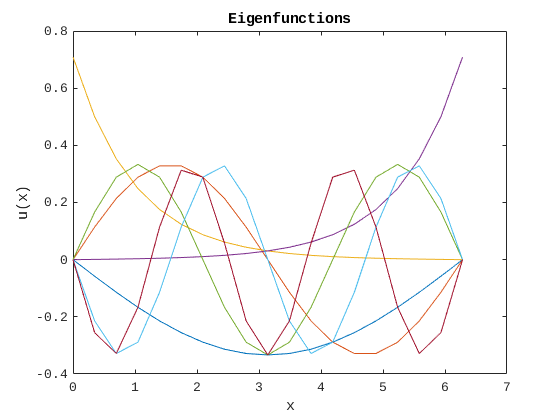


% Plot eigenfunctions
figure()
plot(x,V(:,1:7))
title('Eigenfunctions')
xlabel('x')
ylabel('u(x)')

Using radial basis function generated finite differences RBF-FD, I was able to recover the eigenfunctions of our equation, but I was not able to impose the boundary conditions.

## Collocation Solution (Generalized Eigenvalue Solution) No Boundary Condition

n = 10;                             % Number of nodes
m = 0.25;                           % Gaussian RBF shape parameter
dx = 2*pi/(n);                      % Node spacing
x = (0:n)' * dx;                    % Nodes
DA = collocD(x,m,phi,phi_xx);       % Differential collocation matrix
A = colloc(x,m,phi);                % Collocation matrix

% Compute eigenvalues and coefficient eigenvectors
[V,D] = eigs(DA,A,7,'smallestabs');

% Store eigenvalues
eigVals = diag(D,0)

eigVals =   -0.250508213235443
   0.999999999999983
   1.000000000000406
  -1.001232620128411
  -2.246846872048863
  -3.976646222134344
  -6.222455206279133


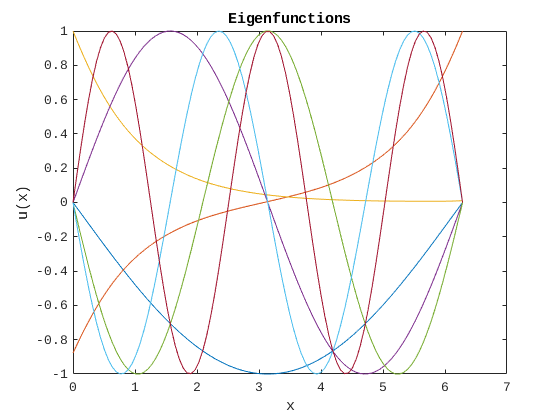

% Plot eigenfunctions
t = linspace(0,2*pi,100);
PHI = intColloc(x,t,m,phi);
plot(t,PHI*V  ./ max(abs(PHI*V)))
title('Eigenfunctions')
xlabel('x')
ylabel('u(x)')

To find the eigenvalues and eigenfunctions of our equation without the boundary condtions. The eigenvalues were found by solving the standard generalized eigenvalue problem. Without the boundary conditions, we recover the exponential eigenfunctions as well. 

## Constrained Eigenvalue Problem Using Collocation Method

n = 20 - 1;                         % Number of nodes
m = 0.5;                            % Gaussian RBF shape parameter
dx = 2*pi/(n);                      % Node spacing
x = (0:n)' * dx;                    % Nodes
DA = collocD(x,m,phi,phi_xx);       % Differential collocation matrix
A = colloc(x,m,phi);                % Collocation matrix

% Compute null space of boundary constraints
C = [phi(x(1),x',m); 
     phi(x(end),x',m)];
tmp = null(C);

% Pad zeros to make null space square
nullC = zeros(n+1);
nullC(:,1:size(tmp,2)) = tmp;

% Solve generalized eignevalue problem for smallest eigenvalues in modulus
[eigVecs,D] = eigs(DA*nullC,A*nullC,3,'smallestabs');
eigVecs = nullC*eigVecs;

% Store eigenvalues
eigVals = diag(D,0)

eigVals =   -0.250023355178581
  -1.000032315900735
  -2.249971059741266


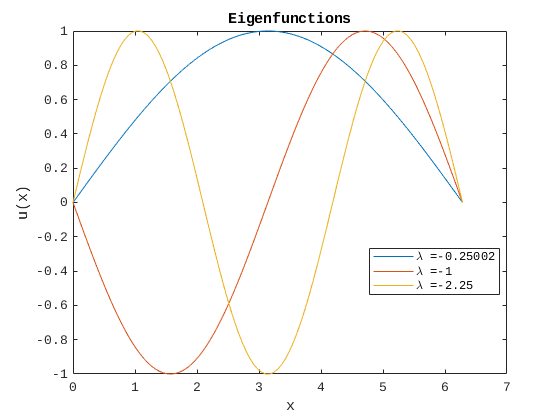


% Plot eigenfunctions
t = linspace(0,2*pi,100)';
PHI = intColloc(x,t,m,phi);
modes = PHI*eigVecs  ./ max(abs(PHI*eigVecs));

figure()
plot(t,modes)
title('Eigenfunctions')
xlabel('x')
ylabel('u(x)')
legend(strcat('\lambda = ', string(eigVals(1))), ...
    strcat('\lambda = ', string(eigVals(2))), ...
    strcat('\lambda = ', string(eigVals(3))), ...
    'Location',"best")

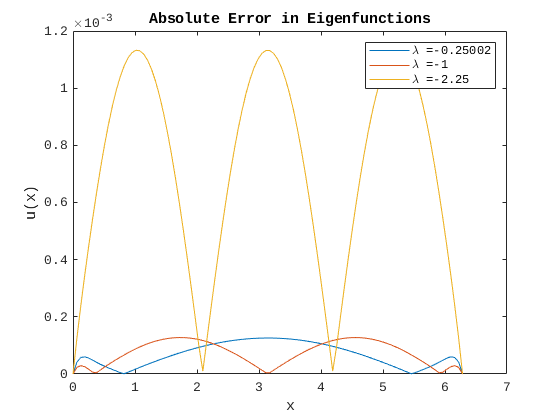


% Plot error in eigenfunctions
trueModes = [1,-1,1] .* sin(([1,2,3]/2) .* t);

figure()
plot(t,abs(modes - trueModes))
title('Absolute Error in Eigenfunctions')
xlabel('x')
ylabel('u(x)')
legend(strcat('\lambda = ', string(eigVals(1))), ...
    strcat('\lambda = ', string(eigVals(2))), ...
    strcat('\lambda = ', string(eigVals(3))), ...
    'Location','northeast')

Now, for the interesting part! To solve the eigenvalue problem with boundary conditions, we need to impose some sort of constraint on to the eigenvectors. To do this we can solve for the eigenvalues in the nullspace of the constraint. Solving our system in the nullspace raises an issue; the nullspace matrix is not square. One way to work around this issue is to pad columns of zeros to the nullspace to make it square. The zeros act as extra dimensions that do not affect the solution of the eigenvectors. The extra dimensions go to zero when we compute the eigenfunction from the RBF. Thus, after imposing the nullspace constraint, the problem comes down to solving the generalized eigenvalue problem. 

From the plots above, we can see that the only solutions that we are recovering are the desired sinusoidal modes of our system. The error in the eigenfunctions is nothing special but that might be due to the choice of basis. A possible improvement would be to use polyharmonic splines with a few appened polynomials over Gaussian RBFs. The choice of basis is really endless though, the collocation method is not limited to RBFs

Another place of improvement would be to replace the padding of zeros with some more formal method. Unless the zero padding can be shown to not affect the solutions, we will want an alternative.

# Function Defintions

%--------------------------------------------------%
% Generate the collocation matrix of our data points
%
% x = nodes in domain
% m = shape parameter
% phi = RBF function

function A = colloc(x, m, phi)
    % Generate collocation matrix
    [XI,XJ] = meshgrid(x);
    A = phi(XI,XJ,m);
end

% Create interpolant matrix
function A = intColloc(x,xi,m,phi)
    [XI,XJ] = meshgrid(x,xi);
    A = phi(XI,XJ,m);
end

% Discretize second derivative operator
function D = discretizeD2(x, phi, phi_xx, m)
    n = length(x);
    
    % Generate collocation matrix
    A = colloc(x, m, phi);
    
    % Deiscretize operator
    D = zeros(n);
    D(1,1) = 1;
    D(end,end) = 1;
    for i = 2:n-1
        % Compute second derivative of RBF at xi
        L = phi_xx(x(i), x, m);
        
        % Populate ith row with operator weights
        D(i,:) = A\L;
    end
end

% Differentiation Collocation matrix
function A = collocD(x,m,phi,phi_xx)
    % Generate collocation matrix
    A = zeros(length(x));
    [XI,XJ] = meshgrid(x);
    A([1,end],:) = phi(XI([1,end],:),XJ([1,end],:),m);
    A(2:end-1,:) = phi_xx(XI(2:end-1,:),XJ(2:end-1,:),m);
end